# Avoid Obstacles Using Reinforcement Learning for Mobile Robots

This example uses Deep Deterministic Policy Gradient (DDPG) based reinforcement learning to develop a strategy for a mobile robot to avoid obstacles. For a brief summary of the DDPG algorithm, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879). 

This example scenario trains a mobile robot to avoid obstacles given range sensor readings that detect obstacles in the map. The objective of the reinforcement learning algorithm is to learn what controls (linear and angular velocity), the robot should use to avoid colliding into obstacles. This example uses an occupancy map of a known environment to generate range sensor readings, detect obstacles, and check collisions the robot may make. The range sensor readings are the observations for the DDPG agent, and the linear and angular velocity controls are the action.

### Load Map

Load a map matrix, `simpleMap`, that represents the environment for the robot.

load Environment1 BW
%load Environment2 BW
%load Environment3 BW

mapMatrix = BW;
mapScale = 1;

### Range Sensor Parameters

Next, set up a `rangeSensor` object which simulates a noisy range sensor. The range sensor readings are considered observations by the agent. Define the angular positions of the range readings, the max range, and the noise parameters.

scanAngles = -3*pi/8:pi/12:3*pi/8; %angulos lidar
maxRange = 70;%range
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

### Robot Parameters

The action of the agent is a two-dimensional vector $a = [v , \omega] $ where $v$ and $\omega$ are the linear and angular velocities of our robot. The DDPG agent uses normalized inputs for both the angular and linear velocities, meaning the actions of the agent are a scalar between -1 and 1, which is multiplied by the `maxLinSpeed` and `maxAngSpeed` parameters to get the actual control. Specify this maximum linear and angular velocity.

Also, specify the initial position of the robot as `[x y theta]`.

% Max speed parameters
maxLinSpeed = 0.9; %lineal speed
maxAngSpeed = 0.9; %angular speed

%%%%route1envieronment1%%%%%
initX = 34; %start point x
initY = 31; %start point y
%%%%%%%%%%%%%%
initTheta = pi/2;%ang init

### Show Map and Robot Positions

To visualize the actions of the robot, create a figure. Start by showing the occupancy map and plot the initial position of the robot.

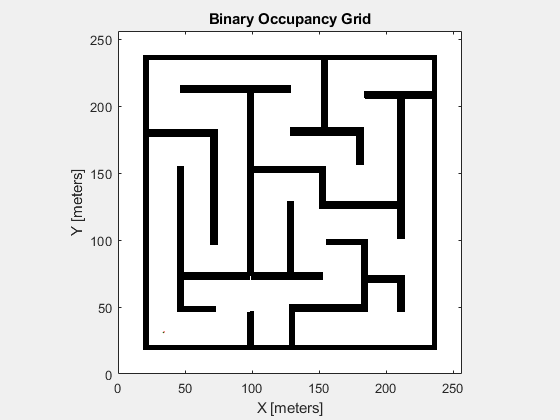

fig = figure("Name","BW");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

### Environment Interface

Create an environment model that takes the action, and gives the observation and reward signals. Specify the provided example model name, ex`ampleHelperAvoidObstaclesMobileRobot`, the simulation time parameters, and the agent block name.

mdl = "exampleHelperAvoidObstaclesMobileRobot";
Tfinal = 1000;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

Open the model.

open_system(mdl)

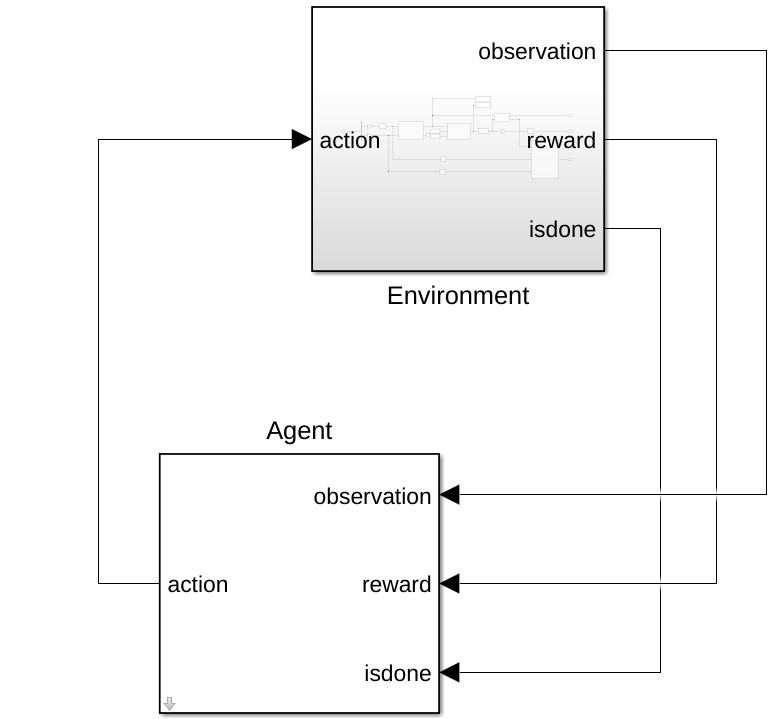

The model contains the `Environment` and `Agent` blocks. The `Agent` block is not defined yet.

Inside the `Environment` Subsystem block, you should see a model for simulating the robot and sensor data. The subsystem takes in the action, generates the observation signal based on the range sensor readings, and calculates the reward based on the distance from obstacles, and the effort of the action commands.

open_system(mdl + "/Environment")

Define observation parameters, `obsInfo`, using the `rlNumericSpec` object and giving the lower and upper limit for the range readings with enough elements for each angular position in the range sensor.

obsInfo = rlNumericSpec([numel(scanAngles) 1],...
    "LowerLimit",zeros(numel(scanAngles),1),...
    "UpperLimit",ones(numel(scanAngles),1)*maxRange);
numObservations = obsInfo.Dimension(1);

Define action parameters, `actInfo`. The action is the control command vector, $a = [v , \omega] $, normalized to $[-1, 1]$.

numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);

Build the environment interface object using [`rlSimulinkEnv`](docid:rl_ref.mw_12cc40dc-3191-4a23-af71-1625696c1a14). Specify the model, agent block name, observation parameters, and action parameters. Set the reset function for the simulation using `exampleHelperRLAvoidObstaclesResetFcn`. This function restarts the simulation by placing the robot in a new random location to begin avoiding obstacles. 

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)exampleHelperRLAvoidObstaclesResetFcn(in,scanAngles,maxRange,mapMatrix);
env.UseFastRestart = "On";

For another example that sets up a Simulink® environment for training, see [Create Simulink Environment and Train Agent](docid:rl_ug.mw_873bd3fc-b713-4e71-b776-9758762d592c).

## DDPG Agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    featureInputLayer(numObservations, "Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","CriticStateFC1")
    reluLayer("Name","CriticRelu1")
    fullyConnectedLayer(25,"Name","CriticStateFC2")];
actionPath = [
    featureInputLayer(numActions,"Normalization","none","Name","Action")
    fullyConnectedLayer(25,"Name","CriticActionFC1")];
commonPath = [
    additionLayer(2,"Name","add")
    reluLayer("Name","CriticCommonRelu")
    fullyConnectedLayer(1,"Name","CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"CriticStateFC2","add/in1");
criticNetwork = connectLayers(criticNetwork,"CriticActionFC1","add/in2");
criticNetwork = dlnetwork(criticNetwork);

Next, specify options for the critic optimizer using `rlOptimizerOptions`.

Finally, create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [rlQValueFunction](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

criticOptions = rlOptimizerOptions("LearnRate",1e-3,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,"ObservationInputNames","State","ActionInputNames","Action");

A DDPG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Finally, construct the actor in a similar manner as the critic. For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

actorNetwork = [
    featureInputLayer(numObservations,"Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","actorFC1")
    reluLayer("Name","actorReLU1")
    fullyConnectedLayer(50, "Name","actorFC2")
    reluLayer("Name","actorReLU2")
    fullyConnectedLayer(2, "Name","actorFC3")
    tanhLayer("Name","Action")];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions("LearnRate",1e-4,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

### Create DDPG agent object

Specify the agent options.

agentOpts = rlDDPGAgentOptions(...
    "SampleTime",sampleTime,...
    "ActorOptimizerOptions",actorOptions,...
    "CriticOptimizerOptions",criticOptions,...
    "DiscountFactor",0.995, ...
    "MiniBatchSize",128, ...
    "ExperienceBufferLength",1e6); 

agentOpts.NoiseOptions.Variance = 0.1;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Create the `rlDDPGAgent` object. The `obstacleAvoidanceAgent` variable is used in the model for the `Agent` block.

obstacleAvoidanceAgent = rlDDPGAgent(actor,critic,agentOpts);
open_system(mdl + "/Agent")

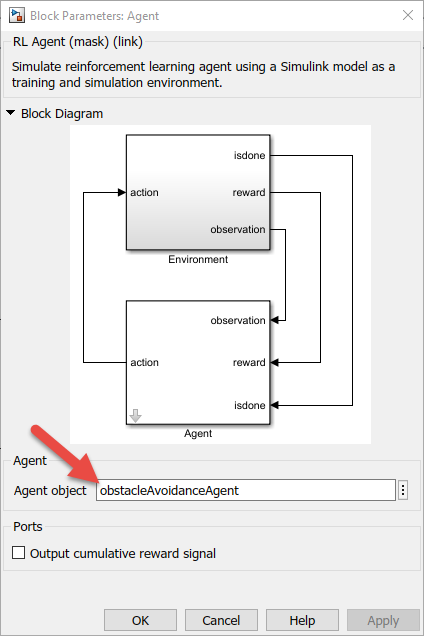

## Reward

The reward function for the agent is modeled as shown.

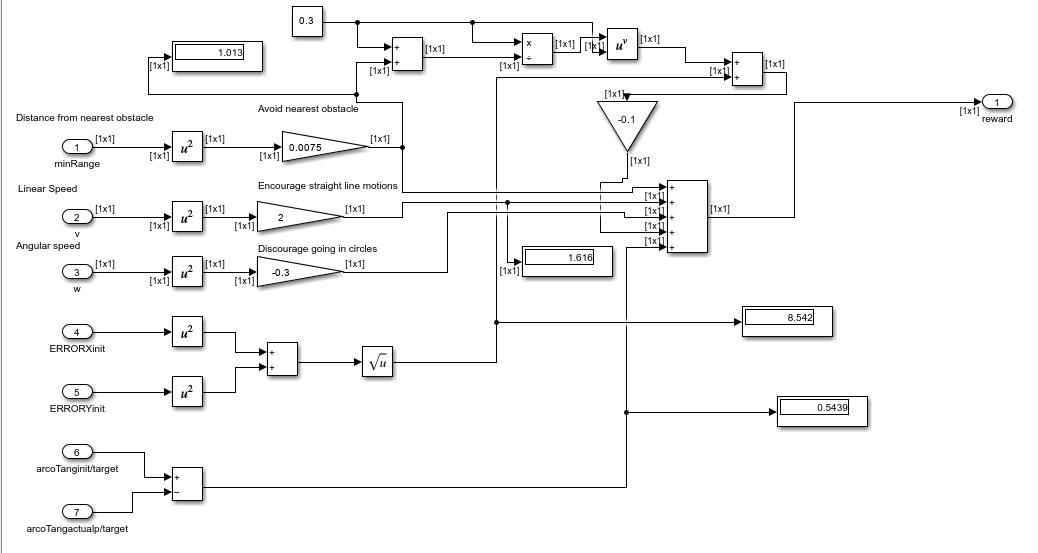

The agent is rewarded to avoid the nearest obstacle, which minimizes the worst-case scenario. Additionally, the agent is given a positive reward for higher linear speeds, and is given a negative reward for higher angular speeds. This rewarding strategy discourages the agent's behavior of going in circles. Tuning your rewards is key to properly training an agent, so your rewards vary depending on your application.

% porfavor, aqui haz que estas variables de target vayan a simulink con un
% bloque de from workspace
targetX = 221;
targetY = 220;

## Train Agent

maxEpisodes = 200;

maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",9999, ...
    "Verbose", true, ...
    "Plots","training-progress");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally-intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true; % Toggle this to true for training. 

if doTraining
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
end

Episode:   1/200 | Episode reward: -27037.31 | Episode steps: 1012 | Average reward: -27037.31 | Step Count: 1012 | Episode Q0:     0.00


Episode:   2/200 | Episode reward: -17352.90 | Episode steps:  644 | Average reward: -22195.11 | Step Count: 1656 | Episode Q0:    -0.06


Episode:   3/200 | Episode reward: -43279.86 | Episode steps: 1671 | Average reward: -29223.36 | Step Count: 3327 | Episode Q0:    -0.18


Episode:   4/200 | Episode reward: -7925.69 | Episode steps:  299 | Average reward: -23898.94 | Step Count: 3626 | Episode Q0:    -0.47


Episode:   5/200 | Episode reward: -23151.34 | Episode steps:  893 | Average reward: -23749.42 | Step Count: 4519 | Episode Q0:    -0.84


Episode:   6/200 | Episode reward: -13150.76 | Episode steps:  497 | Average reward: -21982.98 | Step Count: 5016 | Episode Q0:    -1.38


Episode:   7/200 | Episode reward: -30684.89 | Episode steps: 1232 | Average reward: -23226.11 | Step Count: 6248 | Episode Q0:    -2.07


Episode:   8/200 | Episode reward: -8410.92 | Episode steps:  313 | Average reward: -21374.21 | Step Count: 6561 | Episode Q0:    -3.05


Episode:   9/200 | Episode reward: -7888.55 | Episode steps:  298 | Average reward: -19875.80 | Step Count: 6859 | Episode Q0:    -4.24


Episode:  10/200 | Episode reward: -12094.46 | Episode steps:  473 | Average reward: -19097.67 | Step Count: 7332 | Episode Q0:    -5.65


Episode:  11/200 | Episode reward: -8295.10 | Episode steps:  312 | Average reward: -18115.62 | Step Count: 7644 | Episode Q0:    -7.35


Episode:  12/200 | Episode reward: -14087.80 | Episode steps:  552 | Average reward: -17779.96 | Step Count: 8196 | Episode Q0:    -9.32


Episode:  13/200 | Episode reward: -15052.53 | Episode steps:  560 | Average reward: -17570.16 | Step Count: 8756 | Episode Q0:   -11.71


Episode:  14/200 | Episode reward: -26760.93 | Episode steps: 1012 | Average reward: -18226.65 | Step Count: 9768 | Episode Q0:   -14.56


Episode:  15/200 | Episode reward: -7247.97 | Episode steps:  272 | Average reward: -17494.73 | Step Count: 10040 | Episode Q0:   -18.09


Episode:  16/200 | Episode reward: -18122.73 | Episode steps:  708 | Average reward: -17533.98 | Step Count: 10748 | Episode Q0:   -22.08


Episode:  17/200 | Episode reward: -10932.70 | Episode steps:  412 | Average reward: -17145.67 | Step Count: 11160 | Episode Q0:   -26.74


Episode:  18/200 | Episode reward: -21785.15 | Episode steps:  838 | Average reward: -17403.42 | Step Count: 11998 | Episode Q0:   -30.88


Episode:  19/200 | Episode reward: -34542.83 | Episode steps: 1342 | Average reward: -18305.50 | Step Count: 13340 | Episode Q0:   -32.53


Episode:  20/200 | Episode reward: -9117.94 | Episode steps:  343 | Average reward: -17846.12 | Step Count: 13683 | Episode Q0:   -34.23


Episode:  21/200 | Episode reward: -54754.82 | Episode steps: 2168 | Average reward: -19603.67 | Step Count: 15851 | Episode Q0:   -36.07


Episode:  22/200 | Episode reward: -29700.68 | Episode steps: 1141 | Average reward: -20062.63 | Step Count: 16992 | Episode Q0:   -37.81


Episode:  23/200 | Episode reward: -57784.88 | Episode steps: 2245 | Average reward: -21702.73 | Step Count: 19237 | Episode Q0:   -39.83


Episode:  24/200 | Episode reward: -7285.89 | Episode steps:  274 | Average reward: -21102.03 | Step Count: 19511 | Episode Q0:   -41.74


Episode:  25/200 | Episode reward: -42767.15 | Episode steps: 1647 | Average reward: -21968.63 | Step Count: 21158 | Episode Q0:   -43.70


Episode:  26/200 | Episode reward: -43908.08 | Episode steps: 1727 | Average reward: -22812.46 | Step Count: 22885 | Episode Q0:   -45.74


Episode:  27/200 | Episode reward: -57997.53 | Episode steps: 2248 | Average reward: -24115.61 | Step Count: 25133 | Episode Q0:   -47.73


Episode:  28/200 | Episode reward: -10603.90 | Episode steps:  415 | Average reward: -23633.05 | Step Count: 25548 | Episode Q0:   -49.77


Episode:  29/200 | Episode reward: -25396.62 | Episode steps:  999 | Average reward: -23693.86 | Step Count: 26547 | Episode Q0:   -51.86


Episode:  30/200 | Episode reward: -28306.32 | Episode steps: 1098 | Average reward: -23847.61 | Step Count: 27645 | Episode Q0:   -53.95


Episode:  31/200 | Episode reward: -43842.89 | Episode steps: 1702 | Average reward: -24492.62 | Step Count: 29347 | Episode Q0:   -56.07


Episode:  32/200 | Episode reward: -39320.64 | Episode steps: 1561 | Average reward: -24955.99 | Step Count: 30908 | Episode Q0:   -58.41


Episode:  33/200 | Episode reward: -21395.86 | Episode steps:  842 | Average reward: -24848.11 | Step Count: 31750 | Episode Q0:   -60.24


Episode:  34/200 | Episode reward: -91020.09 | Episode steps: 3511 | Average reward: -26794.34 | Step Count: 35261 | Episode Q0:   -62.53


Episode:  35/200 | Episode reward: -30199.94 | Episode steps: 1157 | Average reward: -26891.65 | Step Count: 36418 | Episode Q0:   -64.82


Episode:  36/200 | Episode reward: -38070.65 | Episode steps: 1500 | Average reward: -27202.17 | Step Count: 37918 | Episode Q0:   -67.07


Episode:  37/200 | Episode reward: -13805.67 | Episode steps:  524 | Average reward: -26840.11 | Step Count: 38442 | Episode Q0:   -69.20


Episode:  38/200 | Episode reward: -79945.52 | Episode steps: 3111 | Average reward: -28237.62 | Step Count: 41553 | Episode Q0:   -71.48


Episode:  39/200 | Episode reward: -75558.83 | Episode steps: 2941 | Average reward: -29450.98 | Step Count: 44494 | Episode Q0:   -73.73


Episode:  40/200 | Episode reward: -235522.96 | Episode steps: 8821 | Average reward: -34602.78 | Step Count: 53315 | Episode Q0:   -75.98


Episode:  41/200 | Episode reward: -61663.40 | Episode steps: 2322 | Average reward: -35262.80 | Step Count: 55637 | Episode Q0:   -78.53


Episode:  42/200 | Episode reward: -117822.18 | Episode steps: 4455 | Average reward: -37228.50 | Step Count: 60092 | Episode Q0:   -80.82


Episode:  43/200 | Episode reward: -25479.00 | Episode steps:  966 | Average reward: -36955.25 | Step Count: 61058 | Episode Q0:   -83.23


Episode:  44/200 | Episode reward: -32608.49 | Episode steps: 1242 | Average reward: -36856.46 | Step Count: 62300 | Episode Q0:   -85.58


Episode:  45/200 | Episode reward: -68047.68 | Episode steps: 2628 | Average reward: -37549.60 | Step Count: 64928 | Episode Q0:   -87.86


Episode:  46/200 | Episode reward: -48751.45 | Episode steps: 1875 | Average reward: -37793.12 | Step Count: 66803 | Episode Q0:   -90.20


Episode:  47/200 | Episode reward: -48734.84 | Episode steps: 1910 | Average reward: -38025.92 | Step Count: 68713 | Episode Q0:   -92.47


Episode:  48/200 | Episode reward: -61617.48 | Episode steps: 2366 | Average reward: -38517.41 | Step Count: 71079 | Episode Q0:   -94.73


Episode:  49/200 | Episode reward: -39378.07 | Episode steps: 1489 | Average reward: -38534.98 | Step Count: 72568 | Episode Q0:   -97.29


Episode:  50/200 | Episode reward: -12485.71 | Episode steps:  480 | Average reward: -38013.99 | Step Count: 73048 | Episode Q0:   -99.55


Episode:  51/200 | Episode reward: -25156.40 | Episode steps:  950 | Average reward: -37976.37 | Step Count: 73998 | Episode Q0:  -101.92


Episode:  52/200 | Episode reward: -17792.77 | Episode steps:  689 | Average reward: -37985.17 | Step Count: 74687 | Episode Q0:  -104.22


Episode:  53/200 | Episode reward: -31978.89 | Episode steps: 1296 | Average reward: -37759.15 | Step Count: 75983 | Episode Q0:  -106.55


Episode:  54/200 | Episode reward: -10238.02 | Episode steps:  401 | Average reward: -37805.40 | Step Count: 76384 | Episode Q0:  -108.97


Episode:  55/200 | Episode reward: -17511.93 | Episode steps:  696 | Average reward: -37692.61 | Step Count: 77080 | Episode Q0:  -111.36


Episode:  56/200 | Episode reward: -25754.77 | Episode steps: 1043 | Average reward: -37944.69 | Step Count: 78123 | Episode Q0:  -113.72


Episode:  57/200 | Episode reward: -31531.34 | Episode steps: 1221 | Average reward: -37961.62 | Step Count: 79344 | Episode Q0:  -116.00


Episode:  58/200 | Episode reward: -21995.03 | Episode steps:  881 | Average reward: -38233.30 | Step Count: 80225 | Episode Q0:  -118.43


Episode:  59/200 | Episode reward: -10469.75 | Episode steps:  400 | Average reward: -38284.92 | Step Count: 80625 | Episode Q0:  -120.75


Episode:  60/200 | Episode reward: -8890.78 | Episode steps:  338 | Average reward: -38220.85 | Step Count: 80963 | Episode Q0:  -123.16


Episode:  61/200 | Episode reward: -7007.85 | Episode steps:  264 | Average reward: -38195.11 | Step Count: 81227 | Episode Q0:  -125.43


Episode:  62/200 | Episode reward: -9648.06 | Episode steps:  376 | Average reward: -38106.31 | Step Count: 81603 | Episode Q0:  -127.86


Episode:  63/200 | Episode reward: -6225.99 | Episode steps:  234 | Average reward: -37929.78 | Step Count: 81837 | Episode Q0:  -130.22


Episode:  64/200 | Episode reward: -12632.15 | Episode steps:  489 | Average reward: -37647.21 | Step Count: 82326 | Episode Q0:  -132.59


Episode:  65/200 | Episode reward: -10221.90 | Episode steps:  392 | Average reward: -37706.68 | Step Count: 82718 | Episode Q0:  -134.95


Episode:  66/200 | Episode reward: -7880.33 | Episode steps:  297 | Average reward: -37501.84 | Step Count: 83015 | Episode Q0:  -137.39


Episode:  67/200 | Episode reward: -6847.37 | Episode steps:  259 | Average reward: -37420.13 | Step Count: 83274 | Episode Q0:  -139.71


Episode:  68/200 | Episode reward: -6516.03 | Episode steps:  246 | Average reward: -37114.75 | Step Count: 83520 | Episode Q0:  -142.13


Episode:  69/200 | Episode reward: -62214.84 | Episode steps: 2341 | Average reward: -37668.19 | Step Count: 85861 | Episode Q0:  -144.43


Episode:  70/200 | Episode reward: -6277.70 | Episode steps:  236 | Average reward: -37611.38 | Step Count: 86097 | Episode Q0:  -146.97


Episode:  71/200 | Episode reward: -124989.59 | Episode steps: 4880 | Average reward: -39016.08 | Step Count: 90977 | Episode Q0:  -149.43


Episode:  72/200 | Episode reward: -33697.05 | Episode steps: 1245 | Average reward: -39096.01 | Step Count: 92222 | Episode Q0:  -151.60


Episode:  73/200 | Episode reward: -6194.21 | Episode steps:  233 | Average reward: -38064.19 | Step Count: 92455 | Episode Q0:  -154.17


Episode:  74/200 | Episode reward: -16243.78 | Episode steps:  608 | Average reward: -38243.35 | Step Count: 93063 | Episode Q0:  -156.67


Episode:  75/200 | Episode reward: -34470.20 | Episode steps: 1291 | Average reward: -38077.41 | Step Count: 94354 | Episode Q0:  -159.07


Episode:  76/200 | Episode reward: -22794.39 | Episode steps:  848 | Average reward: -37655.14 | Step Count: 95202 | Episode Q0:  -161.41


Episode:  77/200 | Episode reward: -228951.25 | Episode steps: 8607 | Average reward: -41074.21 | Step Count: 103809 | Episode Q0:  -163.88


Episode:  78/200 | Episode reward: -18692.30 | Episode steps:  690 | Average reward: -41235.98 | Step Count: 104499 | Episode Q0:  -166.50


Episode:  79/200 | Episode reward: -89791.38 | Episode steps: 3372 | Average reward: -42523.87 | Step Count: 107871 | Episode Q0:  -168.75


Episode:  80/200 | Episode reward: -52574.76 | Episode steps: 1982 | Average reward: -43009.24 | Step Count: 109853 | Episode Q0:  -171.28


Episode:  81/200 | Episode reward: -19997.35 | Episode steps:  745 | Average reward: -42532.33 | Step Count: 110598 | Episode Q0:  -173.70


Episode:  82/200 | Episode reward: -127187.24 | Episode steps: 4873 | Average reward: -44289.66 | Step Count: 115471 | Episode Q0:  -176.28


Episode:  83/200 | Episode reward: -111627.99 | Episode steps: 4244 | Average reward: -46094.31 | Step Count: 119715 | Episode Q0:  -178.65


Episode:  84/200 | Episode reward: -26243.79 | Episode steps:  979 | Average reward: -44798.78 | Step Count: 120694 | Episode Q0:  -181.05


Episode:  85/200 | Episode reward: -35431.91 | Episode steps: 1330 | Average reward: -44903.42 | Step Count: 122024 | Episode Q0:  -183.48


Episode:  86/200 | Episode reward: -63529.18 | Episode steps: 2381 | Average reward: -45412.59 | Step Count: 124405 | Episode Q0:  -185.75


Episode:  87/200 | Episode reward: -7147.73 | Episode steps:  269 | Average reward: -45279.43 | Step Count: 124674 | Episode Q0:  -188.25


Episode:  88/200 | Episode reward: -7992.65 | Episode steps:  302 | Average reward: -43840.37 | Step Count: 124976 | Episode Q0:  -190.82


Episode:  89/200 | Episode reward: -16204.69 | Episode steps:  634 | Average reward: -42653.29 | Step Count: 125610 | Episode Q0:  -193.13


Episode:  90/200 | Episode reward: -10705.42 | Episode steps:  408 | Average reward: -38156.94 | Step Count: 126018 | Episode Q0:  -195.53


Episode:  91/200 | Episode reward: -26117.39 | Episode steps:  984 | Average reward: -37446.02 | Step Count: 127002 | Episode Q0:  -197.91


Episode:  92/200 | Episode reward: -9717.30 | Episode steps:  361 | Average reward: -35283.92 | Step Count: 127363 | Episode Q0:  -200.51


Episode:  93/200 | Episode reward: -9613.16 | Episode steps:  366 | Average reward: -34966.61 | Step Count: 127729 | Episode Q0:  -202.76


Episode:  94/200 | Episode reward: -48472.05 | Episode steps: 2071 | Average reward: -35283.88 | Step Count: 129800 | Episode Q0:  -205.33


Episode:  95/200 | Episode reward: -11555.29 | Episode steps:  442 | Average reward: -34154.03 | Step Count: 130242 | Episode Q0:  -207.51


Episode:  96/200 | Episode reward: -12246.56 | Episode steps:  478 | Average reward: -33423.93 | Step Count: 130720 | Episode Q0:  -209.90


Episode:  97/200 | Episode reward: -11961.03 | Episode steps:  468 | Average reward: -32688.46 | Step Count: 131188 | Episode Q0:  -212.50


Episode:  98/200 | Episode reward: -12215.51 | Episode steps:  479 | Average reward: -31700.42 | Step Count: 131667 | Episode Q0:  -214.89


Episode:  99/200 | Episode reward: -26442.10 | Episode steps: 1068 | Average reward: -31441.70 | Step Count: 132735 | Episode Q0:  -217.30


Episode: 100/200 | Episode reward: -14014.62 | Episode steps:  549 | Average reward: -31472.27 | Step Count: 133284 | Episode Q0:  -219.52


Episode: 101/200 | Episode reward: -11169.44 | Episode steps:  434 | Average reward: -31192.54 | Step Count: 133718 | Episode Q0:  -221.99


Episode: 102/200 | Episode reward: -65563.39 | Episode steps: 2581 | Average reward: -32147.95 | Step Count: 136299 | Episode Q0:  -224.21


Episode: 103/200 | Episode reward: -44549.08 | Episode steps: 1712 | Average reward: -32399.35 | Step Count: 138011 | Episode Q0:  -226.66


Episode: 104/200 | Episode reward: -51644.77 | Episode steps: 1991 | Average reward: -33227.49 | Step Count: 140002 | Episode Q0:  -229.09


Episode: 105/200 | Episode reward: -46027.16 | Episode steps: 1797 | Average reward: -33797.79 | Step Count: 141799 | Episode Q0:  -231.38


Episode: 106/200 | Episode reward: -228157.19 | Episode steps: 9028 | Average reward: -37845.84 | Step Count: 150827 | Episode Q0:  -233.79


Episode: 107/200 | Episode reward: -58878.95 | Episode steps: 2236 | Average reward: -38392.79 | Step Count: 153063 | Episode Q0:  -236.00


Episode: 108/200 | Episode reward: -167374.27 | Episode steps: 6546 | Average reward: -41300.38 | Step Count: 159609 | Episode Q0:  -238.45


Episode: 109/200 | Episode reward: -236365.82 | Episode steps: 9209 | Average reward: -45818.30 | Step Count: 168818 | Episode Q0:  -240.88


Episode: 110/200 | Episode reward: -265444.85 | Episode steps: 10000 | Average reward: -50949.38 | Step Count: 178818 | Episode Q0:  -243.06


Episode: 111/200 | Episode reward: -258826.19 | Episode steps: 10000 | Average reward: -55985.75 | Step Count: 188818 | Episode Q0:  -245.93


Episode: 112/200 | Episode reward: -263418.74 | Episode steps: 10000 | Average reward: -61061.16 | Step Count: 198818 | Episode Q0:  -248.23


Episode: 113/200 | Episode reward: -174109.48 | Episode steps: 6616 | Average reward: -64418.83 | Step Count: 205434 | Episode Q0:  -250.64


Episode: 114/200 | Episode reward: -260965.19 | Episode steps: 10000 | Average reward: -69385.49 | Step Count: 215434 | Episode Q0:  -253.05


Episode: 115/200 | Episode reward: -264305.66 | Episode steps: 10000 | Average reward: -74467.17 | Step Count: 225434 | Episode Q0:  -255.35


Episode: 116/200 | Episode reward: -264750.56 | Episode steps: 10000 | Average reward: -79604.57 | Step Count: 235434 | Episode Q0:  -257.81


Episode: 117/200 | Episode reward: -263129.05 | Episode steps: 10000 | Average reward: -84730.20 | Step Count: 245434 | Episode Q0:  -260.14


Episode: 118/200 | Episode reward: -263417.40 | Episode steps: 10000 | Average reward: -89868.23 | Step Count: 255434 | Episode Q0:  -262.71


Episode: 119/200 | Episode reward: -264445.13 | Episode steps: 10000 | Average reward: -93912.84 | Step Count: 265434 | Episode Q0:  -265.23


Episode: 120/200 | Episode reward: -263969.18 | Episode steps: 10000 | Average reward: -99066.67 | Step Count: 275434 | Episode Q0:  -267.65


Episode: 121/200 | Episode reward: -262779.11 | Episode steps: 10000 | Average reward: -101822.46 | Step Count: 285434 | Episode Q0:  -270.27


## Simulate

Use the trained agent to simulate the robot driving in the map and avoiding obstacles.

set_param("exampleHelperAvoidObstaclesMobileRobot","StopTime","850");
out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");

## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `exampleHelperAvoidObstaclesPosePlot`.

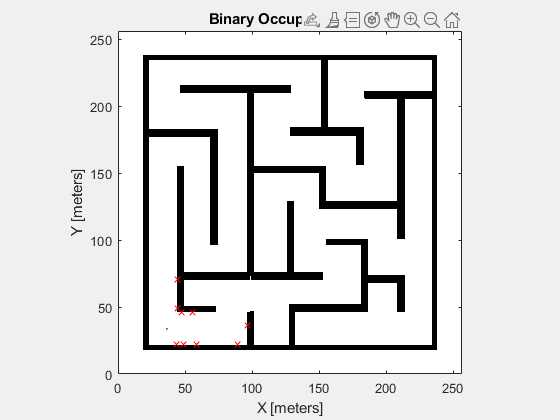

for i = 1:5:size(out.range,3)
   u = out.pose(i,:);
   r = out.range(:,:,i);
   exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
end

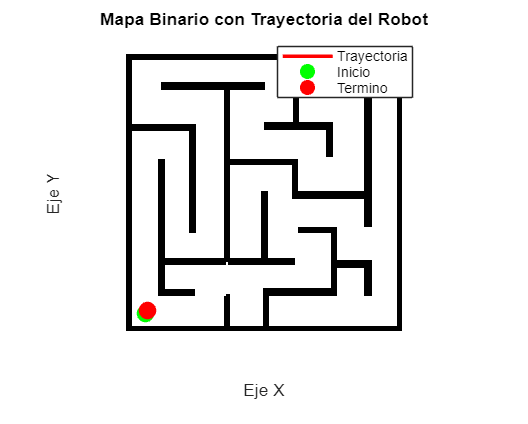

% Crear una figura
figure;

% Invertir los valores del mapa binario
BW_inverted = imcomplement(BW);

% Mostrar el mapa binario invertido como una imagen de fondo
imshow(BW_inverted);
hold on; % Mantener el gráfico actual para superponer la trayectoria

% Definir los límites del gráfico usando las dimensiones de tu mapa 2D
xLimits = [1 size(BW, 2)];
yLimits = [1 size(BW, 1)];
xlim(xLimits);
ylim(yLimits);

% Crear una matriz vacía para almacenar la trayectoria del robot
trajectory = [];

% Iterar a través de los datos de la trayectoria y trazar la trayectoria del robot
for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    % Ajustar las coordenadas del eje Y
    u(2) = (-1) * (u(2) - 256);
    % Aquí puedes realizar cualquier otra operación necesaria con 'u'
    trajectory = [trajectory; u];
end

% Trazar la trayectoria en el mapa 2D
plot(trajectory(:,1), trajectory(:,2), 'r-', 'LineWidth', 2);

% Etiquetas y título
xlabel('Eje X');
ylabel('Eje Y');
title('Mapa Binario con Trayectoria del Robot');

% Marcar el punto de inicio con color verde
startPoint = trajectory(1,:);
plot(startPoint(1), startPoint(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

% Marcar el punto de termino con color rojo
endPoint = trajectory(end,:);
plot(endPoint(1), endPoint(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Mostrar la leyenda
legend('Trayectoria', 'Inicio', 'Termino');

% Habilitar la cuadrícula
grid on;


% Desactivar el modo de espera para permitir que la figura se muestre correctamente
drawnow;